# R-C filters and Square Waves

Rasnow 4 Dec 24

We saw the R-C series circuit responded to a sine wave by the voltages Vr and Vc changing amplitude AND phase as a function of frequency. Specifically the Bode plot showed Vr and Vc were always 90 degrees apart, and +-45 degrees from the source phase and equal amplitude at the corner frequency, $f_c = \frac{1}{2\pi RC$. 

Now I want to explore what happens when the excitation to an R-C series circuit is a square wave. Are the output voltages also square waves with amplitudes and phases that vary with frequency? All we need to do is disconnect the function generator's SIN output from the voltage divider and replace it with the SQU output in Fig. 1. 

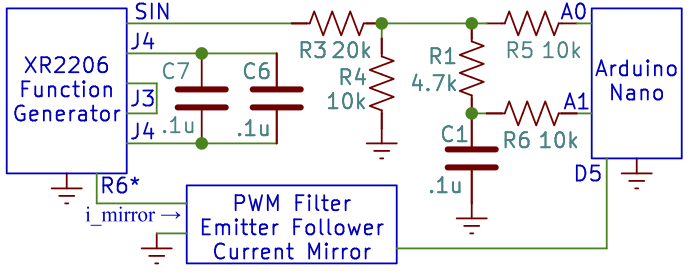

        Figure 1. Schematic to measure frequency response of the R1+C1 series circuit, but substitute function generator's SIN output with a square wave, SQU. 

% clear; close all;
oscope4; % initialize

initializing arduino ...


We should adjust the trigger (trim) threshold to the mean of the square wave, and probably want Fourier deskewing, but make sure to observe the artifacts deskewing produces for a square wave -- both spline or Fourier algorithms don't work well when the data suddenly changes (i.e., $\frac{dV}{dt}$ is large). 

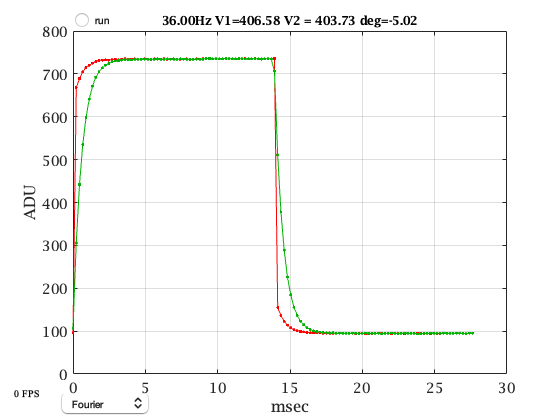

dat.trimThresh = mean(dat.data(:,1)); 
dat.skew.Value = 3; % set Fourier deskewing

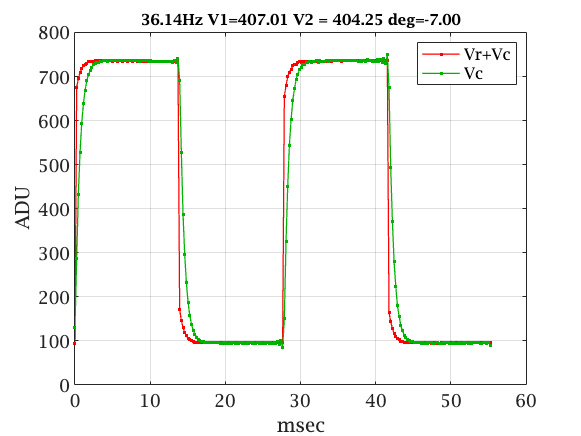

dat.runOnce = true; oscope4;
legend('Vr+Vc','Vc')

Figure 2. Square wave output of function generator. 

Note that Vc (and Vr) are *not *a square waves. That's what was meant by "sine waves are eigenfunctions of linear operators". Only (pure) sine waves pass through a linear circuit (with complex impedances) with only phase and amplitude shifts. Every other signal gets distorted, i.e., the output is not a (complex) constant times the input. Look at Vr (which is proportional to the circuit's current, i = Vr/R: 

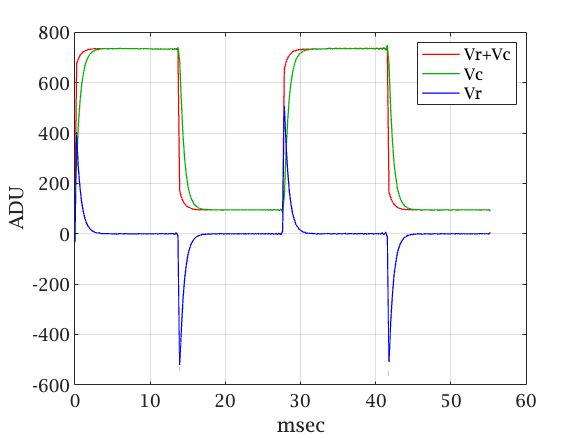

plot(dat.t, [dat.data dat.data(:,1)-dat.data(:,2)]); 
xlabel('msec'); ylabel('ADU'); grid;
legend('Vr+Vc', 'Vc', 'Vr')

Figure 3. Subtracting A0-A1 = Vr. 

Capacitive current $i_c = C\frac{dV}{dt}$ is bidirectional, and we can only measure it with the Arduino because the function generator also has a DC bias and C is at the bottom, as discussed in m16_BodePlot.mlx.  

A second detail I hope you noted is amplitude ringing near the transistions, which is an artifact of both the spline and Fourier deskewing filters. It is called Gibbs Phenomena ([https://en.wikipedia.org/wiki/Gibbs_phenomenon](https://en.wikipedia.org/wiki/Gibbs_phenomenon)) -- Fourier transforms (and splines for that matter) don't follow discontinuities well. 

Repeat with different frequencies, e.g., near $f_c$, 

fc = 1/(2*pi*5.1e3*.1e-6)

fc = 312.0685

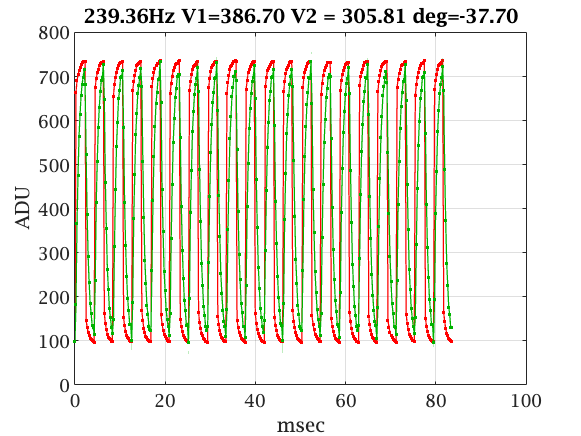

freq2pwm(fc, ard);
dat.runOnce = true; oscope4;

Figure 4. Measurements of A0 and A1 (Vr+Vc and Vc) near the corner frequency. 

The phase shift is close to -45° as expected, and the ratio of the amplitudes is close to 1/sqrt(2) = .707: 

abs(dat.ampl(2))/abs(dat.ampl(1))

ans = 0.6955

But the distortion in the waveforms is more severe -- some of it from the circuit and likely some from the deskewing filter: 

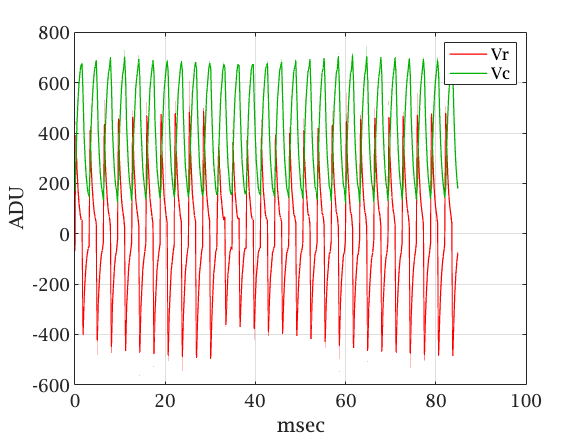

plot(dat.t, [-diff(dat.data')' dat.data(:,2)]); 
legend('Vr','Vc'); grid; xlabel('msec'); ylabel('ADU');

Figure 5. Measured Vr and Vc near $f_c$ look nothing like square waves.

Note how I used Matlab's `diff` function and transposes this time to compute Vr as the first column of the plotted data. 

## Spectrum of a square wave

What does this look like in the frequency domain? Because the Nyquist frequency is close (less than a factor of 10 or decade) above $f_c$, let's lower the frequency to a couple of full periods -- this may take a little tweaking of the PWM value:

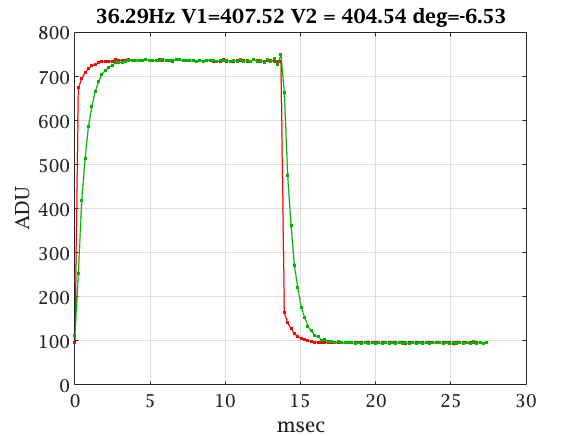

writeline(ard,'p 45');
dat.runOnce = true; oscope4; 

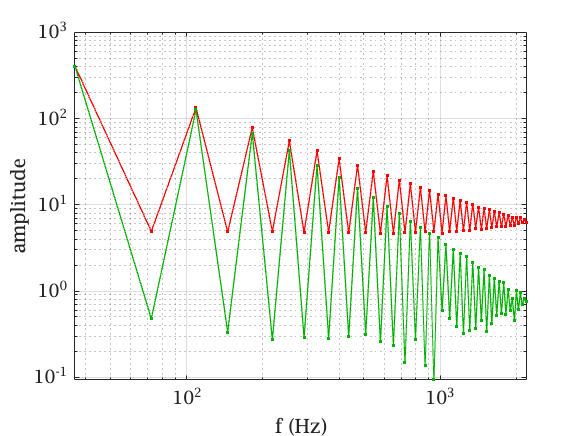

aspectrum(dat.data, dat.sr);
dots;

With data tips, I identified the following frequencies (x) and amplitudes (y):

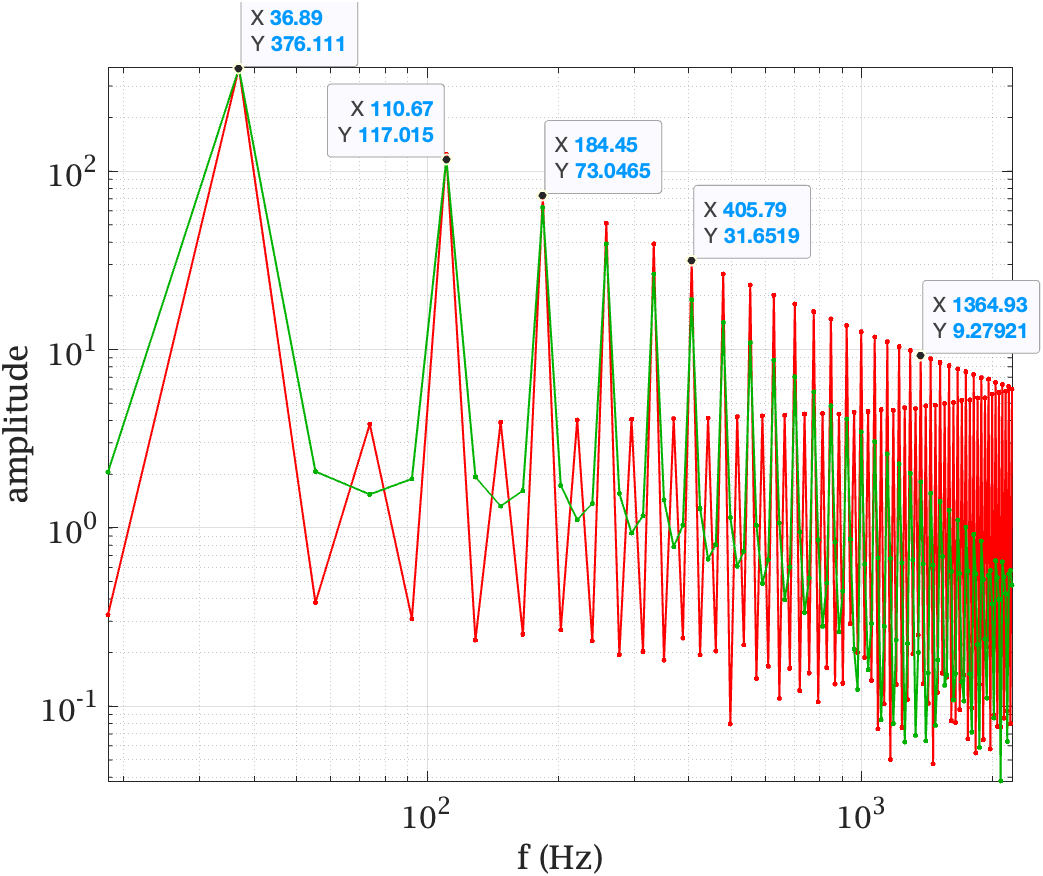

Figure 6. Measured amplitude spectra of Vr+Vc and Vc. 

Dividing the tagged frequencies by the first one yields:

[110.67 184.45 405.79 1364.93] / 36.89

ans =      3     5    11    37


We're seeing discrete odd harmonics, with decreasing amplitudes. But we're also witnessing aliasing -- a reflection of the decreasing harmonics above the Nyquist frequency (the right side of the graph). It might be easier to understand what's reflected artifact in the wrong place and what's real if we simulate and calculate a perfect square wave, and then come back to our measurements.

## Simulating a Square Wave 

Let's imagine a single square wave period of 100 samples measured at 1kHz. The period would be 100samples/(1000 samples/sec) = 0.1 second, corresponding to a frequency = 1/period of 10Hz:

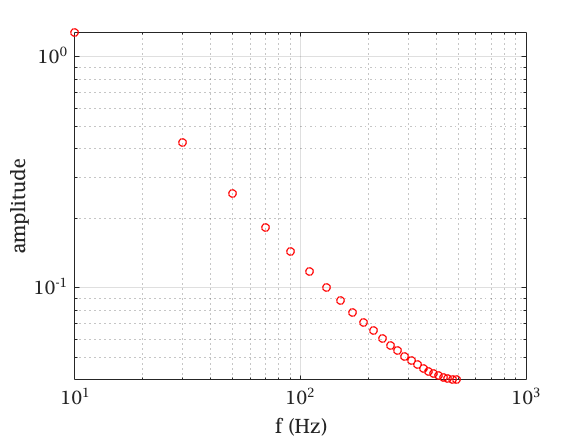

sqWave = [ones(50,1); -ones(50,1)]; % 1 period
[ampl, freq] = aspectrum(sqWave, 1e3); dots('o');

ampl(1:10)'

ans =     1.2734         0    0.4250         0    0.2557         0    0.1834         0    0.1434         0


Figure 7. Amplitude spectra of 1 period of an ideal square wave. 

Like we saw with the measured data, the spectrum consists of "discrete" odd harmonics with decreasing amplitudes. (Note:  old versions of Matlab returned even harmonic amplitudes ~1e-16 due to roundoff errors in floating point numbers.) What does theory predict?

The Fourier transform (from the Wikipedia is): 

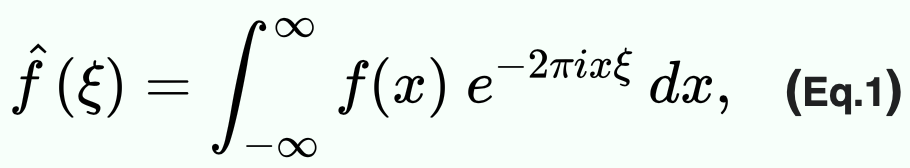

A couple steps are necessary to solve this. First, imagine extending the square wave  periodically to + and - infinity. I won't try to solve this formally (you can look it up in PDE or Fourier Transform texts), but by wave of hand, for frequencies, $\xi$ that aren't integer multiples of the square wave, the phase between $f(x)$ and $e^{-2\pi ix\xi}$ will shift so that somewhere they'll be in phase and somewhere else they'll be out of phase and integrated over the entire domain everything will cancel. Unless the two are phase locked, i.e., $\xi = n/T$ where $T$ is the period of $f(x)$. 

Second, I'm going to skip a bunch of steps and motivation and shortcut to the answer -- again, lots of texts have the missing steps. The sqWave is an odd function as constructed, so we can simplify the integral to a real integral: 


$$\frac{1}{\pi}\int_0^{2\pi}{f(x)sin(nx)dx = \frac{1}{\pi}\int_0^{\pi}{sin(nx)dx -  \frac{1}{\pi}\int_\pi^{2\pi}{sin(nx)dx = \frac{2}{n\pi}[-cos(n\pi)-1] = \frac{4}{n\pi}$ for $n = $ odd.$$


Let's compare the odd amplitudes : 

ampl(1:2:20)'

ans =     1.2734    0.4250    0.2557    0.1834    0.1434    0.1181    0.1007    0.0881    0.0786    0.0712


4/pi ./ (1:2:20)

ans =     1.2732    0.4244    0.2546    0.1819    0.1415    0.1157    0.0979    0.0849    0.0749    0.0670


Close. So a unit amplitude square wave of frequency $f_0$ can be decomposed as  = $\[
\sum_{n=odd}^\infty \frac{4}{n\pi}\sin(n\pi f_0 t)
\]$. 

## Partial sums

Let's look at partial sums by computing the first n = 1:5 nonzero terms of the Fourier series: 

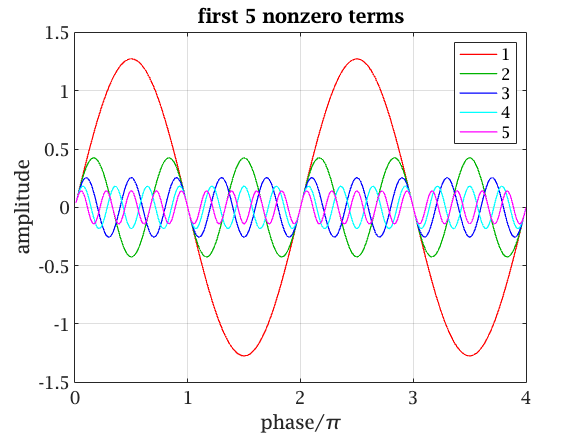

phases = (.01:.01:4)'; % 2 periods = 4*pi radians 
an = zeros(length(phases),5);
for n=1:5
    an(:,n) = 4 / (2*n-1) / pi * sin((2*n-1) * pi * phases); 
end
plot(phases, an); grid;
xlabel('phase/\pi'); ylabel('amplitude'); 
title('first 5 nonzero terms'); legend(string(1:5))

Figure 8. Lowest 5 nonzero Fourier components of a unit square wave.

You see how the harmonics are all in phase at 0:100:400 samples, or every pi radians. Thus at those phases they add up to fill in the "corners" of the sine wave to make it square. And at the fundamental peaks, the even harmonics are of opposite phase and reduce the peak amplitude (while the odd harmonics are in phase). Let's look at partial sums. We have to do some transposes for `cumsum` (see `>> help cumsum`): 

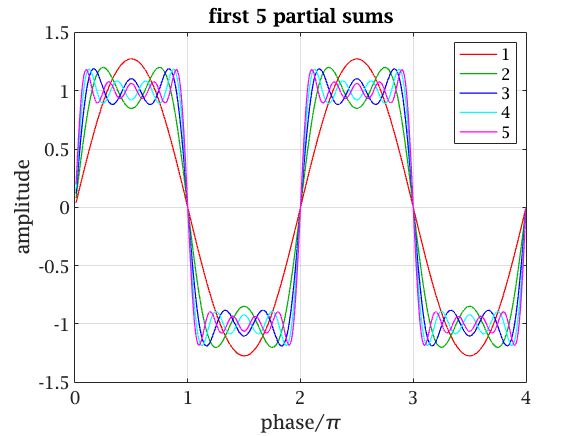

plot(phases, cumsum(an')'); 
xlabel('phase/\pi'); ylabel('amplitude'); 
title('first 5 partial sums');
legend(string(1:5)); grid

Figure 9. Lowest partial sums of the Fourier series of a unit square wave. 

The corners are filling in, and in fact an overshoot is appearing, called "[Gibbs phenomena](https://en.wikipedia.org/wiki/Gibbs_phenomenon)". And the top is getting flatter. As an exercise, I encourage you to explore adding in more terms -- like 10, 100, and 1000, to get a feeling for convergence. Then imagine Fourier doing something like this in 1822 -- presumably with candlelight, slide rule (invented 1620-30), ... no Matlab yet;-(. 

If instead of one period, we had measured N periods, then the fundamental would be at the Nth element of aspectrum (and the N+1th element of the fft -- because the fft's first element is DC or zero frequency), the first nonzero harmonic would be the 3*Nth element, etc. 

## Making a Bode Plot from One Time Series?!

So a square wave has a (discrete) spectrum of harmonics with decreasing amplitudes ... if we normalize these amplitudes by multiplying the 3rd, 5th, etc. harmonic by 3, 5, etc., we should be able to generate the Bode plot from a single time series measurement of a square wave! Here's code that does that  -- starting with the Fourier transform of [Vr+Vc, Vc], that I (approximately) normalize by scaling the fundamental amplitude to 1. Next compute V =  [Vr Vc] by subtracting the (complex) Fourier coefficients (the double transpose preserves the complex phase). I've limited the frequencies to < Nyquist, and used $f_c$ = 308Hz from the previous lab.

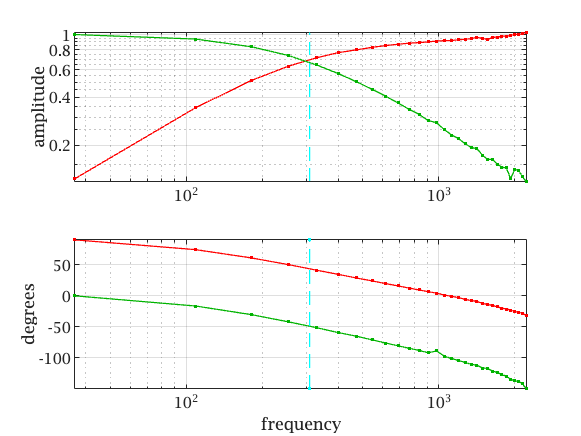

fd = fft(dat.data) / length(dat.data) * 2; 
fV = fd / fd(dat.npds+1,2); % approximate normalization
V = [-diff(fV')' fV(:,2)] ; % Vr Vc
harmonics = V(dat.npds+1:2*dat.npds:floor(end/2),:); % odd harmonics
normalizedHarmonics = harmonics .* (1:2:2*length(harmonics))';
freqs = dat.freq * (1:2:2*length(harmonics)');
bodePlot(freqs, normalizedHarmonics, 308); dots;

Figure 10. Bode plot generated from measuring a single time series using a square wave. 

The phase is a bit off at higher frequencies -- but think about what we've done. Each ADC sample at 2kHz is nearly 180 degrees of phase apart -- hardly a clean sine wave. We numerically corrected for sampling skewing of about 90 degrees of phase at 2kHz. The Fourier component amplitudes are falling as 1/n, so although we started with a square wave of amplitude ~ 360ADU, the input sine wave at $60f_0$ (on the right side of the Bode plot) has amplitude of just ~6ADU, that the capacitor has attenuated by a factor >10 (with sine wave gain was measured ~0.15, attenuation ~6.6, Fig. 11). So no surprise that the Bode plot isn't as clean and accurate as we generated by sweeping a sine wave sequentially across the spectrum (Fig. 11), but considering the data was captured in <1 second vs. 30 seconds, the Fourier method has its uses.

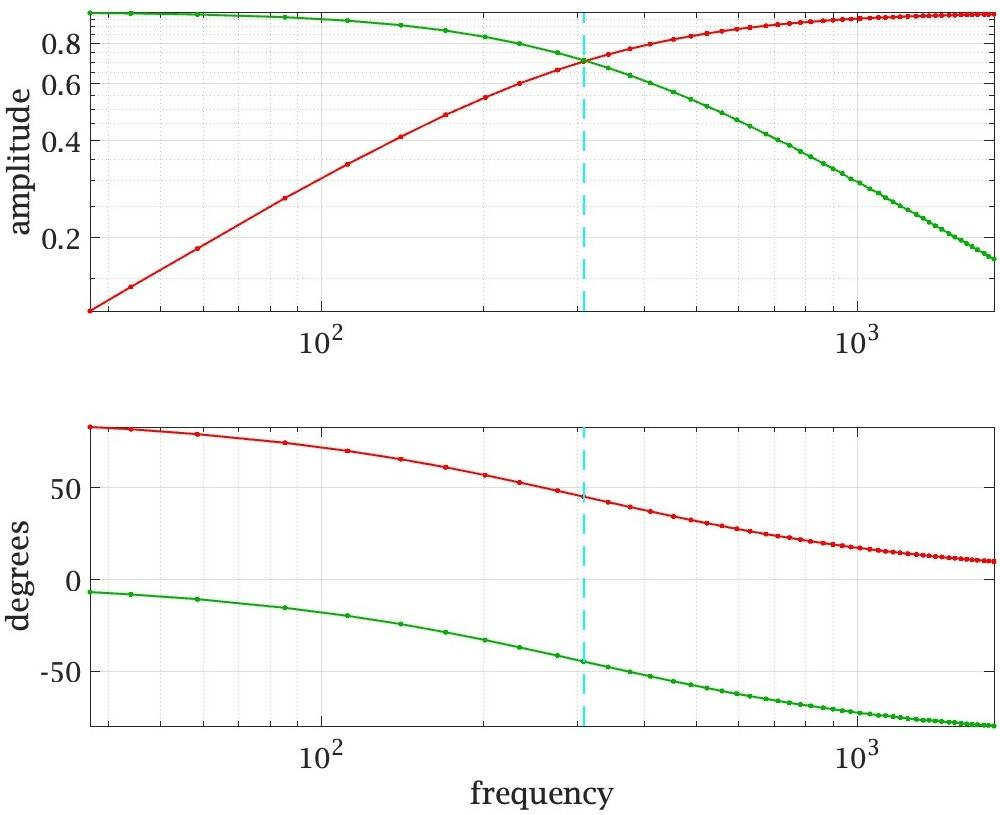

Figure 11. Bode plot generated previously by sweeping a sine wave across 50 frequencies. 

## Concluding remarks

Roger Penrose, one of the smartest living mathematicians has this diagram in the first chapter of his enormous book, "[Road to Reality](https://www.amazon.com/Road-Reality-Complete-Guide-Universe/dp/0679776311)": 

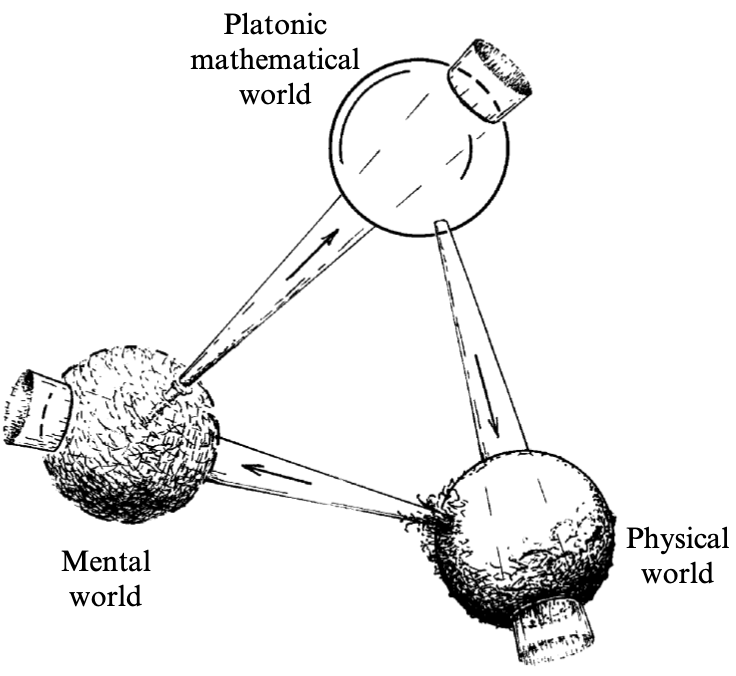

He abstractly represents 3 "worlds" or domains that are "mysteriously" connected: the physical world being the shared reality we live in, with e,g, resistors and capacitors; the Platonic mathematical world which contains mathematical ideas, like Euclid's idealized points and lines, along with Fourier transforms, algebra, etc.; and the world inside our heads consisting of all the things we might imagine and understand. A subset of our mental world consists of or relate to a subset of the mathematical world. A subset of the mathematical universe has an uncanny similarity to a subset of the physical world. And we can internalize, model, and understand (at some level) a subset of the physical world. What we've explored here instantiates some of these diverse connections and domains. Imagine (or better yet, actually build in the physical world) an RC filter connected to a square wave voltage and measure Vr and Vc. The voltage waveforms on the physical resistors and capacitors are what they are in the physical world -- no amount of imagination or desires (or changing the channel to Fox News) will change them. They're just doing what they do according to the laws of E&M and physics. Then there are the mathematical models we've created -- inhabitants of the Platonic mathematical world, built with voltage divider equations, complex `zc.m`, `f2t.m`, etc., following the rules of mathematics (instantiated with Matlab). And both of these seemingly radically different systems produce the same results, the same waveforms!! Why?? What does that tell us?? There are many deep (and not so deep) philosophical lessons, but let's focus on practical ones now. The mathematics we've used here is a good model of the physical phenomena. It exhibits enough complexity to replicate the complicated waveforms of these ciruits. Nobody has found simpler mathematical models that are as accurate, so we should feel lucky to have what we have: 3 parallel universes where we can explore electronic phenomena. Discoveries can be made in any of these worlds, but they shouldn't be believed until verified in at least another world. The more facile we are at moving between these worlds, the better we can validate and calibrate our understanding so it mirrors reality and gives us more power to manipulate and model these worlds. 